**Lee and Shetzen cross correlation technique**

In this programm I will apply the cross correletion technique of Lee and Shetzen to examine the Wiener kernals of the system. After these are found the corresponding Volterra functionals will be determined.

**Loading the data**

load Jochem.mat %loading data file

**Auto correlation property of the GWN data**

Firstly we need to check that the GWN data fullfills the auto-correlation property, the autocorrelation should be equal to the mean of the data squared, which will be 0 in the case of GWN data. The expectation value of the data should also equal 0 for odd, and 1 for even powers of the gwn signal.

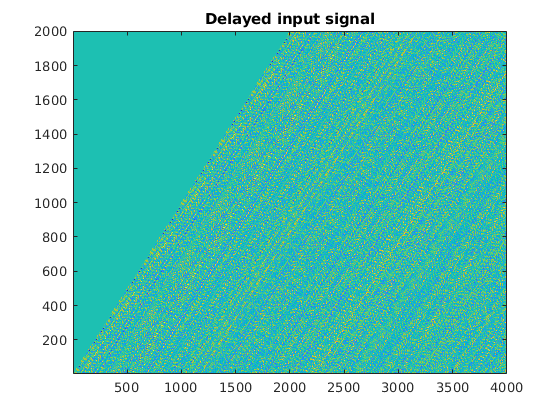

a_corr_gwn=phi_yx2(gwnt,gwnt,2000);

%EGWN1=mean(gwnt); %indeed see that the mean of the gwn signal is about 0
%EGWN2=mean(gwnt.*gwnt); %and that the product has a mean of about 1
disp(max(a_corr_gwn)); %the maximum result from the integral is 0.1475, so the

    0.0436



%gwn signal indeed has about a zero autocorrelation. Note that the result
%varries for different time differences, M, that are used. For M=0 I
%obtain 1, which is expected as these are identical (and the result should
%be a dirac delta which is 1 if the timing is the exact same). For large M
%(eg. M=2000), this results in ~0.04 (so very small). 

**Exploring the wiener function**

P = 0.4862

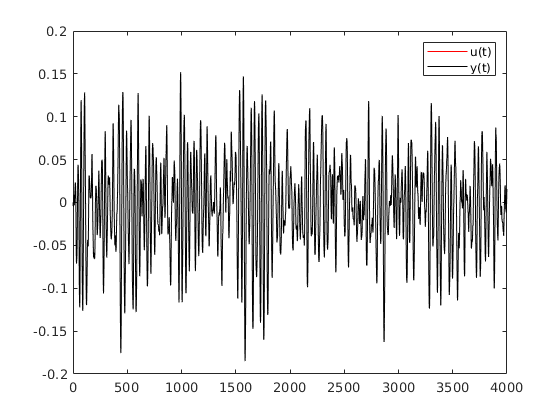

h0 = -0.0011

m1 = 0.0185

m2 = 0.0268

m3 = 0.6907

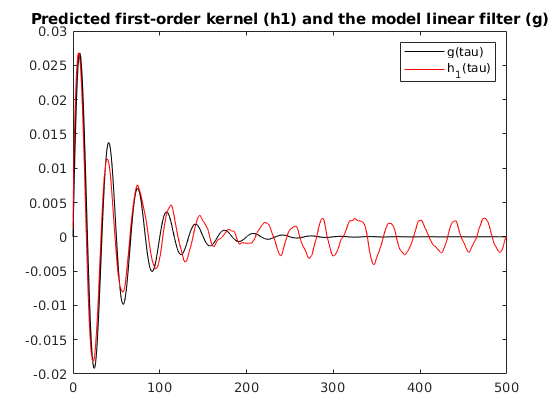

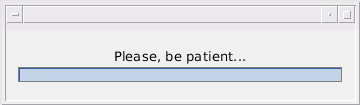

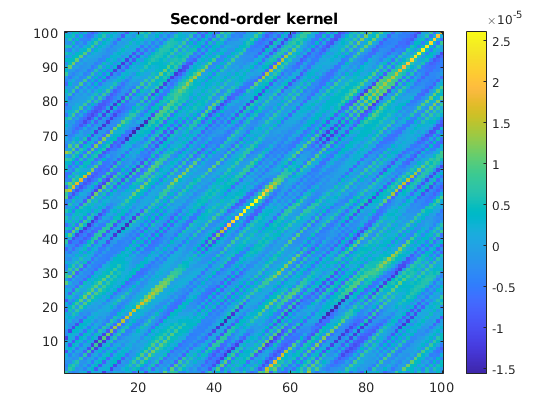

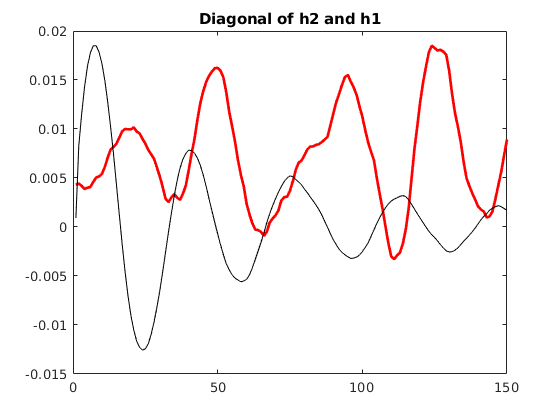

ans = -0.0011

wiener(1,0)